# MATLAB Online with Python

You can run Python code on your desktop if you have the proper Python files setup. Alternatively, you can run Python on MATLAB Online! MATLAB Online maintains a version of Python on the MATLAB servers so that you can successfully run your code that calls Python from MATLAB.

Setup

While you can check which version of Python is installed on the MATLAB servers with

py = pyenv

py =   PythonEnvironment with properties:

          Version: "3.10"
       Executable: "C:\Users\MathWorks\AppData\Local\Programs\Python\Python310\pythonw.exe"
          Library: "C:\Users\MathWorks\AppData\Local\Programs\Python\Python310\python310.dll"
             Home: "C:\Users\MathWorks\AppData\Local\Programs\Python\Python310"
           Status: Loaded
    ExecutionMode: OutOfProcess
        ProcessID: "21380"
      ProcessName: "MATLABPyHost"


you will need to set up and install your chosen libraries. MATLAB Online does not save your online setup preferences, so you will need to do this setup each time you want to execute Python from MATLAB Online. except in the most elementary cases of using the  MATLAB Python Code App. In this simple case, no setup is needed.

Test out the following code snippet in the Python live task:

% Python code input
pycode = [...
"import math as mm",...
"",...
"x = 42",...
"y = mm.sqrt(x)"...
];

try
    [x, y] = pyrun(pycode, ...
         [ "x" "y" ])
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    rethrow(ME)
end

x =   Python int with properties:

    denominator: [1×1 py.int]
           imag: [1×1 py.int]
      numerator: [1×1 py.int]
           real: [1×1 py.int]

    42


y = 6.4807


% Clear temporary variables from workspace and from Python
clear pycode;

## Set up environment

setup

NOTES ABOUT SETUP FUNCTION

# Eclipse 🌑🌒🌓

Analyze the total solar eclipse

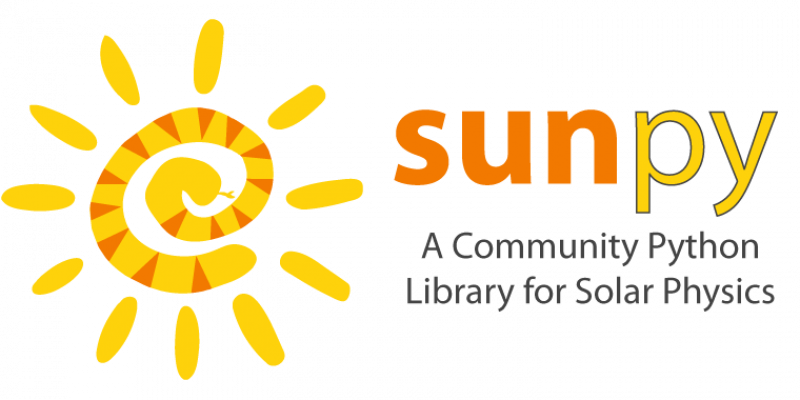

## Resources

- [https://github.com/yanndebray/matlab-with-python-book](https://github.com/yanndebray/matlab-with-python-book)

- [https://docs.sunpy.org/en/stable/generated/gallery/showcase/eclipse_amount.html](https://docs.sunpy.org/en/stable/generated/gallery/showcase/eclipse_amount.html) 

## Context

In this tutorial, we will show how to use MATLAB with the SunPy community Python library for Solar Physics

pipshow("numpy")

% run python file that returns latitude, longitude, and a pandas dataframe
% (lat, lon, df) respectively
[lat, lon, df] = pyrunfile("runpy.py", [ "latitude" "longitude" "df" ])

## Transform Pandas Dataframe to MATLAB Table

% T = table(df)
TT = timetable(df)

% stackedplot(TT)
plot(TT.time,TT.amount)

% San Antonio, Texas
lat = double(lat);
lon = double(lon);
geoscatter(lat,lon, 'filled')

## Export to ipynb and md

%export('livescript.mlx','README.md');
%export('livescript.mlx','notebook.ipynb');

## **For fun: Installing Python packages**

% install scikit-learn
pipinstall("scikit-learn")

% show the install
pipshow("scikit-learn")

% install scipy
pipinstall("scipy")

% show the install
pipshow("scipy")

*© The MathWorks, Inc. 2025*